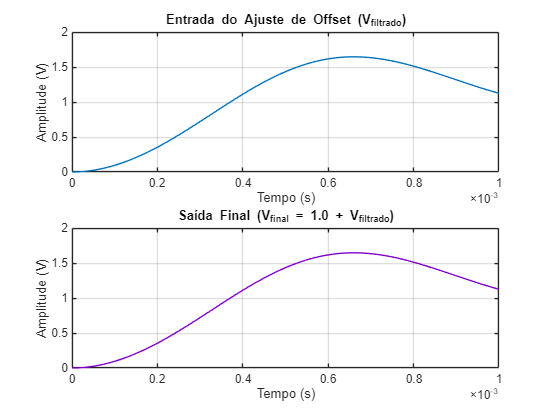

%% Analise_Ajuste_Offset.m
clear; clc; close all;

% Carregar saída do filtro
load('V_filtrado.mat', 'V_filtrado', 't', 'Fs');

% Parâmetros do ajuste
V_offset = 0; % Offset desejado

% Aplicar offset
V_final = V_offset + V_filtrado;

% Plotagem
figure;
subplot(2,1,1);
plot(t, V_filtrado);
title('Entrada do Ajuste de Offset (V_{filtrado})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;

subplot(2,1,2);
plot(t, V_final, 'Color', [0.5 0 0.8]);
title('Saída Final (V_{final} = 1.0 + V_{filtrado})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;